# CMCN Homework 6

#### Vic-Fabienne Schumann, 811165

I got help from Jonas Freimuth

## Task 1 

% read in data to model
% some code using the coupling function
% 
tca_model = readCbModel('data/tcacycle.xml')

tca_model = struct with fields:
               S: [25×28 double]
            mets: {25×1 cell}
               b: [25×1 double]
          csense: [25×1 char]
            rxns: {28×1 cell}
              lb: [28×1 double]
              ub: [28×1 double]
               c: [28×1 double]
       osenseStr: 'max'
           genes: {49×1 cell}
           rules: {28×1 cell}
       geneNames: {49×1 cell}
       compNames: {'Default_Compartment'}
           comps: {'Default_Compartment'}
        proteins: {49×1 cell}
     metFormulas: {25×1 cell}
        metNames: {25×1 cell}
        rxnNames: {28×1 cell}
    rxnECNumbers: {28×1 cell}
      subSystems: {28×1 cell}
     description: 'tcacycle.xml'
    modelVersion: [1×1 struct]
         modelID: 'tcacycle3'



% switch solver
changeCobraSolver('glpk');

Gurobi installed at this location? 
Licence file current? 


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
GLPK Simplex Optimizer, v4.42
1 row, 2 columns, 1 non-zero
Preprocessing...
~     0: obj =   0.000000000e+00  infeas =  0.000e+00
OPTIMAL SOLUTION FOUND BY LP PREPROCESSOR

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
removing: /opt/cobratoolbox/src/analysis/thermo/componentContribution/new
removing: /opt/cobratoolbox/src/analysis/thermo/groupContribution/new
removing: /opt/cobratoolbox/src/analysis/thermo/inchi/new
removing: /opt/cobratoolbox/src/analysis/thermo/molFiles/new
removing: /opt/cobratoolbox/src/analysis/thermo/protons/new
removing: /opt/cobratoolbox/src/analysis/thermo/trainingModel/new
 > isCompatible: glpk is compatible and fully tested with MATLAB R2020b on your type of operating system.



% convert model to include only non-reversible reactions
tca_model_irrevonly = convertToIrreversible(tca_model);

% reduce model now so we have the same model for both exercises
% model reduce removes reactions which are blocked or just never used
tca_model_irrevonly_red = reduceModel(tca_model_irrevonly);

tol = 1.0000e-06

Model reduction in progress ...
93%     [.....................................   ]Perform model consistency check


coupling_res = coupling(tca_model_irrevonly_red);

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

coupling_res

coupling_res =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     3     1     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     0     4     1     3     0     0     0     4     0     0     0     0     0     3     0     0     2     0     4     0     4     0     0     4     3     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     4     4     1     0     0     0     4     0     0     0     0     0     0     0     0     2     0     4     0     4     0     0     4     0     0     4     0     0     4     0     0     0     0    

## Task 2 

changeCobraSolver('lp_solve', 'all')

Attempt to execute SCRIPT mxlpsolve as a function:
/opt/cobratoolbox/src/base/solvers/lp_solve/mxlpsolve.m
 > changeCobraSolver: Solver for LP problems has been set to lp_solve.
 > changeCobraSolver: Solver lp_solve not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver lp_solve not supported for problems of type MILP. No solver set for this problemtype 
 > changeCobraSolver: Solver lp_solve not supported for problems of type MIQP. No solver set for this problemtype 
 > changeCobraSolver: Solver lp_solve not supported for problems of type NLP. No solver set for this problemtype 
 > changeCobraSolver: Solver lp_solve not supported for problems of type QP. No solver set for this problemtype 


ans = logical
   0


opts.nStepsPerPoint = 1000;
opts.nPointsReturned = 100;
opts.maxTime = 14400;

%[~, samples] = sampleCbModel(tca_model_irrevonly_red, [], 'ACHR', opts)

Prepare model for sampling
Original model: 43 rxns 25 metabolites
Reduce model
Model reduction in progress ...
93%     [.....................................   ]Perform model consistency check
Reduced model: 43 rxns 25 metabolites
Create warmup points
Creating warmup points ...
100%    [........................................]
Run sampler for a total of 10000000 steps
ACHR sampling in progress ...
File #	Point #	Step #	Time	#Time left
1	1	0	    0.00	     Inf
0%      [                  0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [                    0%      [       

Unrecognized function or variable 'tca_model_irrevonly'.

The sampled flux values for a given reaction determine its probability distribution. From task 1, choose one pair of fully coupled reactions, one pair of directionally, and one pair of uncoupled reactions. For each pair, determine the correlation coefficient of the distributions using the Matlab function corr, and plot the scatter plot using scatter.

% save("flux_samples_not_reduced.mat", "samples")
load("flux_samples_not_reduced.mat")
samples = transpose(samples);

% selecting coupled reactions and plotting their correlations:
rxn_pair_idcs = zeros(length(unique(coupling_res)), 2);
corr_coefs = zeros(length(unique(coupling_res)), 1);
type_lookup = {'Not coupled' 'Fully coupled' 'Partially coupled' 'Coupled x -> y' 'Coupled x <- y'};

coup_type_vec = unique(coupling_res);

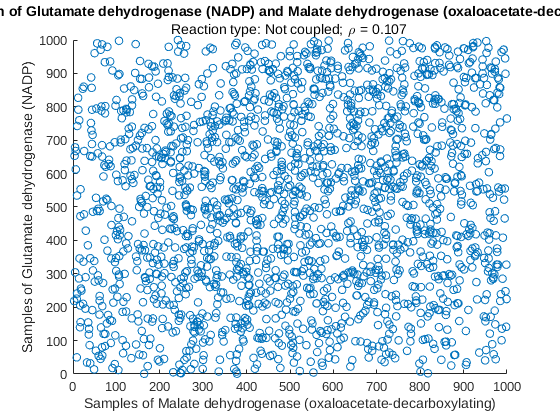

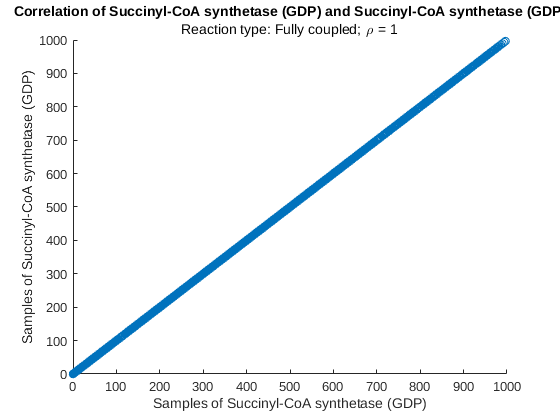

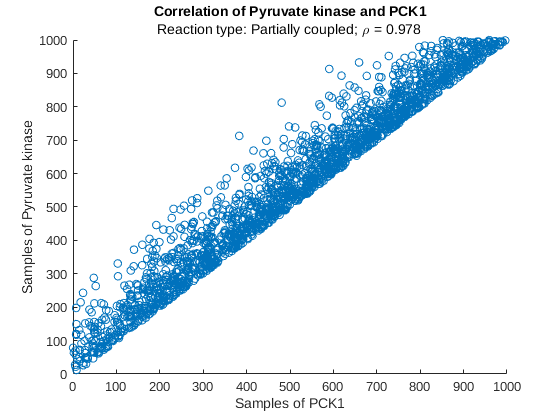

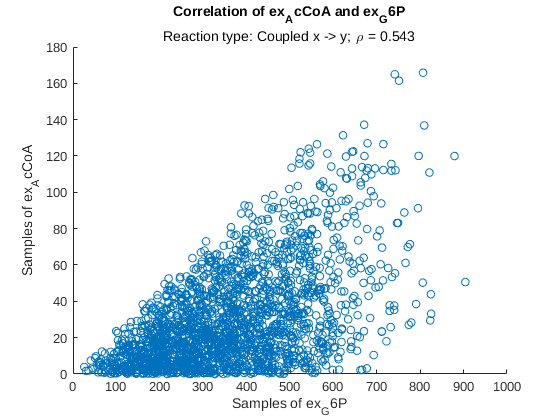

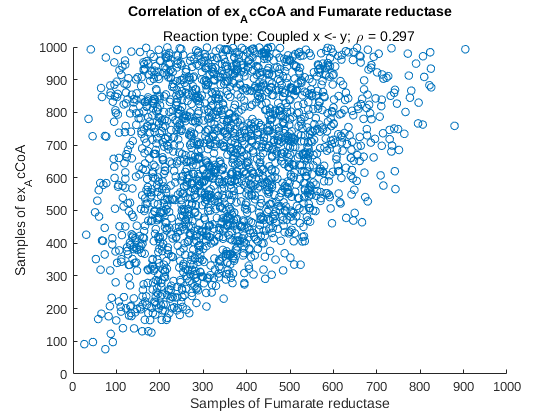


for coup_type_idx = 1:length(coup_type_vec)
    pot_indices = find(coupling_res == coup_type_vec(coup_type_idx));
    
    % sample a random index out of that
    idx = pot_indices(randi(size(find(coupling_res == coup_type_vec(coup_type_idx)), 1)));
    
    % get reaction pairs from the linear index and save to matrix
    rxn_pair_idx_from = ceil(idx / size(tca_model_irrevonly_red.rxns, 1));
    rxn_pair_idx_to = mod(idx, size(tca_model_irrevonly_red.rxns, 1));
    
    rxn_pair_idcs(1, coup_type_idx) = rxn_pair_idx_from;
    rxn_pair_idcs(2, coup_type_idx) = rxn_pair_idx_to;
    
    name_from = tca_model_irrevonly_red.rxnNames(rxn_pair_idx_from);
    name_to = tca_model_irrevonly_red.rxnNames(rxn_pair_idx_to);
    
    corel = corr(samples(:, rxn_pair_idx_from), samples(:, rxn_pair_idx_to));
    
    figure(coup_type_idx);
    
    scatter(samples(:, rxn_pair_idx_from), samples(:, rxn_pair_idx_to))
   
    title('Correlation of ' + string(name_from) + ' and ' + string(name_to))
    subtitle('Reaction type: ' + string(type_lookup(coup_type_idx)) + '; \rho = ' + round(corel, 3))
    xlabel('Samples of ' + string(name_to))
    ylabel('Samples of ' + string(name_from))
    
    
end